% Define constants

rg = 0.0254;
L = 0.4255;
g = 9.81;
K = 1.5;
tau = 0.025;

dt = 0.001; % Time step
t_final = 3; % Total simulation time
num_steps = t_final / dt;
t = 0:dt:t_final;

% Define dynamics \dot{x} = f(x, u) and observation model y = h(x)
f = @(x, u) [ 
    x(2); 
    ((5 * g * rg)/(7 * L)) * sin(x(3)) - (5/7) * ((L/2) - x(1)) * ((rg/L) * x(4))^2 * cos(x(3))^2;
    x(4); 
    -1 * x(4)/tau + (K/tau) * u
    ];

h = @(x) [
    x(1); 
    x(3)
    ]; % ball position and servo angle


syms x1 x2 x3 x4 u_sym dt_sym real

x_sym = [x1; x2; x3; x4];
f_sym_continuous = subs(f(x_sym, u_sym));
f_sym = x_sym + dt_sym * f_sym_continuous;

A_sym = jacobian(f_sym, x_sym);
A_func = matlabFunction(A_sym, 'Vars', {x_sym, u_sym, dt_sym});

C_func = @(x) [1 0 0 0; 0 0 1 0];

ref = 0.010 * sin( (2*pi/t_final) * t );


ref =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005


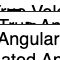

% TODO: replace the below with ode45
X_true = zeros(4, num_steps+1);
X_true(:,1) = [0; 0; 0; 0];

for k = 1:num_steps
    xk = X_true(:, k);
    uk = ref(k);
    dxk = f(xk, uk);
    X_true(:, k+1) = xk + dt * dxk;
end

% Create noisy measurements of h(x)
pos_noise_std = 0.00002;  % e.g. 2 mm standard deviation
ang_noise_std = 0.000001; % e.g. 0.01 rad standard deviation

disp(["Position noise per time step (mm)", pos_noise_std/dt * 1000]);
disp(["Angular noise per time step (rad)", ang_noise_std/dt]);

Y_meas = zeros(2, num_steps+1);
for k = 1:num_steps+1
    true_output = h(X_true(:,k));
    noise_vec = [pos_noise_std*randn; ang_noise_std*randn];
    Y_meas(:,k) = true_output + noise_vec;
end

%%%%% The extended Luenberger observer algorithm
% Initialize our estimate
x_0 = [0, 0, 0, 0];
hat_x = x_0;
hat_x = hat_x(:); 

% Initialize state history (for plotting)
X_est = zeros(4, num_steps);
X_est(:, 1) = hat_x;

% Simulate the observer loop
for k = 1:num_steps
    hat_u = ref(k); 

    A_eval = A_func(hat_x, hat_u, dt);
    C_eval = C_func(hat_x);

    Co = ctrb(A_eval', C_eval');
    rank_Co = rank(Co);
    % disp(['Rank of Controllability Matrix: ', num2str(rank_Co)]);

    if rank_Co < 4
        poles = [-1, -1.5, -2, -2.5];
    else
        poles = [-1, -1.5, -3, -3.5];
    end

    L = place(A_eval', C_eval', poles)';
    hat_y = h(hat_x);
    
    y = Y_meas(:, k);
    
    dot_hat_x = f(hat_x, hat_u) + L * (y - hat_y);
    hat_x = hat_x + dt * dot_hat_x;
    X_est(:, k+1) = hat_x;
end

%% Compare: true vs. estimated states
figure('Name','Observer Performance','NumberTitle','off');

% Ball Position
subplot(4,1,1)
plot(t, X_true(1,:), 'k-', 'LineWidth',1.5); hold on;
plot(t, X_est(1,:), 'r--','LineWidth',1.5);
grid on; legend('True Position','Estimated Position','Location','best');
xlabel('Time (s)'); ylabel('Position (m)');
title('Ball Position: True vs Estimated');

% Ball Velocity
subplot(4,1,2)
plot(t, X_true(2,:), 'k-', 'LineWidth',1.5); hold on;
plot(t, X_est(2,:), 'r--','LineWidth',1.5);
grid on; legend('True Velocity','Estimated Velocity','Location','best');
xlabel('Time (s)'); ylabel('Velocity (m/s)');
title('Ball Velocity: True vs Estimated');

% Servo Angle
subplot(4,1,3)
plot(t, X_true(3,:), 'k-', 'LineWidth',1.5); hold on;
plot(t, X_est(3,:), 'b--','LineWidth',1.5);
grid on; legend('True Angle','Estimated Angle','Location','best');
xlabel('Time (s)'); ylabel('Angle (rad)');
title('Servo Angle: True vs Estimated');

% Servo Angular Velocity
subplot(4,1,4)
plot(t, X_true(4,:), 'k-', 'LineWidth',1.5); hold on;
plot(t, X_est(4,:), 'b--','LineWidth',1.5);
grid on; legend('True Angular Velocity','Estimated Angular Velocity','Location','best');
xlabel('Time (s)'); ylabel('Angular Velocity (rad/s)');
title('Servo Angular Velocity: True vs Estimated');